clear all
% At = 0.0154;
% Av = pi*(0.0040)^2;
% a12 = 0.3485;
% a23 = 0.3485;
% a10 = 0.6677;
% a30I = 0.6591;
% g = 9.80665;
% 
  x0 = [0.65;0.1;0.3];

#### *(i) Determine the vectorial relative degree of the system.*

#### Answer

Build the system with symbolic math toolbox.


syms x1 x2 x3 u1 u2 v1 v2 At Av a12 a23 a10 a30I g

% f = [ -x1 + x2^2; x1*x3 + x4; -x1 + x3; x5; -x5+x3^2;]
f1 = -(2^(1/2)*Av*a10*(g*x1)^(1/2) + 2^(1/2)*Av*a12*g^(1/2)*sign(x1 - x2)*abs(x1 - x2)^(1/2))/At;
f2 = (2^(1/2)*Av*a12*g^(1/2)*sign(x1 - x2)*abs(x1 - x2)^(1/2) - 2^(1/2)*Av*a23*g^(1/2)*sign(x2 - x3)*abs(x2 - x3)^(1/2))/At;
f3 = - (2^(1/2)*Av*a30I*(g*x3)^(1/2) - 2^(1/2)*Av*a23*g^(1/2)*sign(x2 - x3)*abs(x2 - x3)^(1/2))/At;
f = [f1; f2; f3]

$$f = \left(\begin{array}{c} -\frac{\sqrt{2}\,\mathrm{Av}\,a_{10}\,\sqrt{g\,x_{1}}+\sqrt{2}\,\mathrm{Av}\,a_{12}\,\sqrt{g}\,\sqrt{\left|x_{1}-x_{2}\right|}\,\mathrm{sign}\left(x_{1}-x_{2}\right)}{\mathrm{At}}\\ \frac{\sqrt{2}\,\mathrm{Av}\,a_{12}\,\sqrt{g}\,\sqrt{\left|x_{1}-x_{2}\right|}\,\mathrm{sign}\left(x_{1}-x_{2}\right)-\sqrt{2}\,\mathrm{Av}\,a_{23}\,\sqrt{g}\,\sqrt{\left|x_{2}-x_{3}\right|}\,\mathrm{sign}\left(x_{2}-x_{3}\right)}{\mathrm{At}}\\ -\frac{\sqrt{2}\,\mathrm{Av}\,\mathrm{a30I}\,\sqrt{g\,x_{3}}-\sqrt{2}\,\mathrm{Av}\,a_{23}\,\sqrt{g}\,\sqrt{\left|x_{2}-x_{3}\right|}\,\mathrm{sign}\left(x_{2}-x_{3}\right)}{\mathrm{At}} \end{array}\right)$$


x = [x1; x2; x3; ]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3} \end{array}\right)$$


% g1 = [ 0; 0; 1; 1; x2;];
% g2 = [ 0; 1; 0; 0; 0; ];
% g = [g1, g2]
g1 = [1/At; 0; 0;];
g2 = [0; 0; 1/At ];
g = [g1 g2];

h1 = x1;
h2 = x3;
 
h = [h1; h2;]

$$h = \left(\begin{array}{c} x_{1}\\ x_{3} \end{array}\right)$$


v = [v1; v2;];
u = [u1; u2;];

m = length(h);
n = length(x);

Since the input and output dimensions `m` are 2 rather than 1, the relative degree becomes a vector `(r1, r2)`.

r = zeros(1,m);
% Calculate relative degree
for i = 1:m
    k = 0;
    lglfh = LgLfh(f,g(:,i),h,x,0)
    while lglfh == zeros(m,1)
        k = k+1;
        lglfh = LgLfh(f,g(:,i),h,x,k) % eq(3.9)
    end
    r(:,i) = k+1;
end

$$lglfh = \left(\begin{array}{c} \frac{1}{\mathrm{At}}\\ 0 \end{array}\right)$$

$$lglfh = \left(\begin{array}{c} 0\\ \frac{1}{\mathrm{At}} \end{array}\right)$$

r

r =      1     1


#### *(ii) Examine the internal dynamics and make a statement about the stability of the zero dynamics.*

#### Answer

Calculate vector `a(x)`:

clear i
syms a [m 1]
for i = 1:m
    a(i) = Lfh(f,h(i),x,r(i)); % eq(3.12)   
end
a

$$a = \left(\begin{array}{c} -\frac{\sqrt{2}\,\mathrm{Av}\,a_{10}\,\sqrt{g\,x_{1}}+\sqrt{2}\,\mathrm{Av}\,a_{12}\,\sqrt{g}\,\sqrt{\left|x_{1}-x_{2}\right|}\,\mathrm{sign}\left(x_{1}-x_{2}\right)}{\mathrm{At}}\\ -\frac{\sqrt{2}\,\mathrm{Av}\,\mathrm{a30I}\,\sqrt{g\,x_{3}}-\sqrt{2}\,\mathrm{Av}\,a_{23}\,\sqrt{g}\,\sqrt{\left|x_{2}-x_{3}\right|}\,\mathrm{sign}\left(x_{2}-x_{3}\right)}{\mathrm{At}} \end{array}\right)$$

Calculate decoupling matrix `B(x)`:

clear i
syms B [m m]
for i = 1:m
    B(i,:) = LgLfh(f,g,h(i),x,r(i)-1); % eq(3.11)   
end
B

$$B = \left(\begin{array}{cc} \frac{1}{\mathrm{At}} & 0\\ 0 & \frac{1}{\mathrm{At}} \end{array}\right)$$

The determinant of matrix `B` is 1, therefore it is nonsigular. This guarantees that the relative degree is well defined. 

The diffeomosphism that shows the linear structrue of this feedback system is:

clear i k
syms z [n 1]
syms xi [sum(r) 1] % linearized states
k = 1;
for i = 1:m
    for j = 1:r(i)
        xi(k) = Lfh(f,h(i),x,j-1); % eq(3.14)
        k = k+1;
    end
end
xi

$$xi = \left(\begin{array}{c} x_{1}\\ x_{3} \end{array}\right)$$

z(1:sum(r)) = xi;

From the given vector `z`, it can be seen that there are 3 internal dynamics, for simplicity, we assign values as follows:

z(3) = x(2);

syms eta eta_dot [n-sum(r) 1] % internal dynamics
eta = z(3)

$$eta = x_{2}$$

z

$$z = \left(\begin{array}{c} x_{1}\\ x_{3}\\ x_{2} \end{array}\right)$$

eta_dot(1) = f(2) + g(2,:)*u;

eta_dot

$$eta\_dot = \frac{\sqrt{2}\,\mathrm{Av}\,a_{12}\,\sqrt{g}\,\sqrt{\left|x_{1}-x_{2}\right|}\,\mathrm{sign}\left(x_{1}-x_{2}\right)-\sqrt{2}\,\mathrm{Av}\,a_{23}\,\sqrt{g}\,\sqrt{\left|x_{2}-x_{3}\right|}\,\mathrm{sign}\left(x_{2}-x_{3}\right)}{\mathrm{At}}$$


eta_zero_dot = subs(eta_dot,xi,zeros(length(xi),1)) % zero dynamics

$$eta\_zero\_dot = -\frac{\sqrt{2}\,\mathrm{Av}\,a_{12}\,\sqrt{g}\,\sqrt{\left|x_{2}\right|}\,\mathrm{sign}\left(x_{2}\right)+\sqrt{2}\,\mathrm{Av}\,a_{23}\,\sqrt{g}\,\sqrt{\left|x_{2}\right|}\,\mathrm{sign}\left(x_{2}\right)}{\mathrm{At}}$$

In order to evaluate the stability of zero dynamics, the most intuitive way is to find its time domain solution.

% syms x2(t) 
% eq = diff(x2,t)== eta_zero_dot
% 
% dsolve(eq)

State `η1` and `η3` are asymptotically stable since they converge to zero as time increases; while `η2 `(or `z4` in the codes) is unstable because it depends on the integral of `u1`.

In this case, one has to introduce a new internal state to cancel out the influence by `u1`. Here we choose:

#### *(iii) Design an output control with the method of exact input-output linearization. Use the reference trajectory *

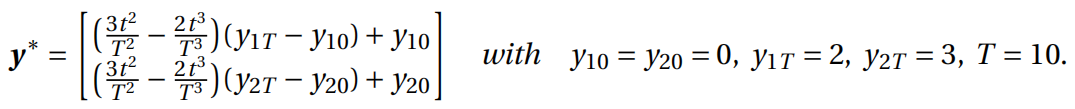

#### Answer

syms y1_ref(t) y2_ref(t) y10 y20 y1T y2T T
% y10 = x0(1);
% y20 = x0(3);
% y1T = 0.2;
% y2T = 0.25;
% T = 80;
% y1_ref = (3*t^2/T^2 - 2*t^3/T^3)*(y1T - y10)+ y10;
% y2_ref = (3*t^2/T^2 - 2*t^3/T^3)*(y2T - y20)+ y20;
% y_ref = [y1_ref; y2_ref;]
% y_ref_dot = diff(y_ref,t)

The state feedback control which decouples and linearizes the I-O dynamics is:

clear i k
syms p [sum(r) 1]
k = 1;

y1T_vec = [y1T; y2T];
for i = 1:m
    v(i) = 0;
    for l = 0:r(i)-1
        v(i) = v(i) - p(k)*(Lfh(f,h(i),x,l) - y1T_vec(i)); % eq(3.26)
        k = k+1;
    end
end


v % introduced new input of the linearized system 

$$v = \left(\begin{array}{c} -p_{1}\,\left(x_{1}-\mathrm{y1T}\right)\\ -p_{2}\,\left(x_{3}-\mathrm{y2T}\right) \end{array}\right)$$

u = B\(-a + v) % control law; eq(3.20)

$$u = \left(\begin{array}{c} \mathrm{At}\,p_{1}\,\mathrm{y1T}-\mathrm{At}\,p_{1}\,x_{1}+\sqrt{2}\,\mathrm{Av}\,a_{10}\,\sqrt{g\,x_{1}}+\sqrt{2}\,\mathrm{Av}\,a_{12}\,\sqrt{g}\,\sqrt{\left|x_{1}-x_{2}\right|}\,\mathrm{sign}\left(x_{1}-x_{2}\right)\\ \mathrm{At}\,p_{2}\,\mathrm{y2T}-\mathrm{At}\,p_{2}\,x_{3}+\sqrt{2}\,\mathrm{Av}\,\mathrm{a30I}\,\sqrt{g\,x_{3}}-\sqrt{2}\,\mathrm{Av}\,a_{23}\,\sqrt{g}\,\sqrt{\left|x_{2}-x_{3}\right|}\,\mathrm{sign}\left(x_{2}-x_{3}\right) \end{array}\right)$$


u = subs(u,[y1T y2T p1 p2],[0.2 0.25 10 10])

$$u = \left(\begin{array}{c} 2\,\mathrm{At}-10\,\mathrm{At}\,x_{1}+\sqrt{2}\,\mathrm{Av}\,a_{10}\,\sqrt{g\,x_{1}}+\sqrt{2}\,\mathrm{Av}\,a_{12}\,\sqrt{g}\,\sqrt{\left|x_{1}-x_{2}\right|}\,\mathrm{sign}\left(x_{1}-x_{2}\right)\\ \frac{5\,\mathrm{At}}{2}-10\,\mathrm{At}\,x_{3}+\sqrt{2}\,\mathrm{Av}\,\mathrm{a30I}\,\sqrt{g\,x_{3}}-\sqrt{2}\,\mathrm{Av}\,a_{23}\,\sqrt{g}\,\sqrt{\left|x_{2}-x_{3}\right|}\,\mathrm{sign}\left(x_{2}-x_{3}\right) \end{array}\right)$$

The coefficients `p1` and `p2` are are coefficients of a Hurwitz polynomial. With this control law the system output will asymptotically converge towards `y∗` .

#### *(iv) Test your results using a *MATLAB / SIMULINK *simulation.*

#### Answer

One can use `matlabFunctionBlock(’blockname’, symexpr)` to convert the symbolic expression to `MATLAB-FUNCTION `block. 

% new_system('Ex3_2_4')
% open_system('Ex3_2_4')
% 
% u = subs(u,[p1, p2],[1 1])
% matlabFunctionBlock('Ex3_2_4/controller', u, y_ref,'Vars',{x, t},'Optimize',false)
% 
% clear u
% syms u1 u2
% u = [u1; u2];
% dx = f + g*u
% y = h
% matlabFunctionBlock('Ex3_2_4/model', y, dx,'Vars',{u, x},'Optimize',false)
% 
% save_system('Ex3_2_4')

Since the section above can be only used once, we commented it for convenience.

From the simulation results in Simulink it can be concluded that the outputs can track the references with a high accuracy, even though the tracking errors increase over time. Therefore, the system is stablized by the feedback control law.